## Backtesting a set of tickers 

The objective of this notebook is to showcase how to backtest a portfolio consisting of a number of tickers and weights.

### Importing market data

initDate = '1-Jan-2014';
symbol = 'AAPL';
aaplusd_yahoo_raw = getMarketDataViaYahoo(symbol, initDate);
aaplusd_yahoo = timeseries([aaplusd_yahoo_raw.Close, aaplusd_yahoo_raw.High, aaplusd_yahoo_raw.Low], datestr(aaplusd_yahoo_raw(:,1).Date));
aaplusd_yahoo.DataInfo.Units = 'USD';
aaplusd_yahoo.Name = symbol;
aaplusd_yahoo.TimeInfo.Format = "dd-mm-yyyy";

### Construct and backtest a portfolio

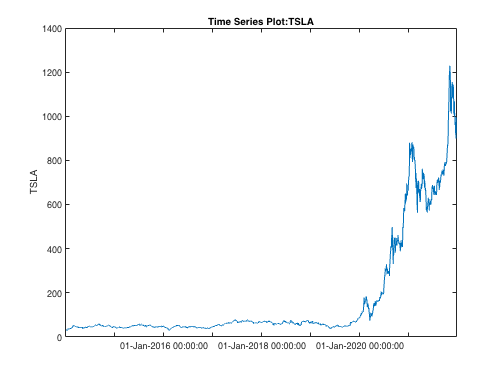

weight_apple = 0.5;
weight_tesla = 0.5;

history = getMarketDataViaYahoo('TSLA', initDate);
apple = getMarketDataViaYahoo('AAPL', initDate);

tsla_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', "TSLA");
apple_price = timeseries(apple.Close, datestr(apple(:,1).Date), 'Name', "AAPL");
tsla_price.plot()

TT = timeseries2timetable([tsla_price apple_price])

TT = 2009×2 timetable
       Time         TSLA      AAPL 
    ___________    ______    ______

    02-Jan-2014     30.02    19.755
    03-Jan-2014    29.912    19.321
    06-Jan-2014      29.4    19.426
    07-Jan-2014    29.872    19.287
    08-Jan-2014    30.256    19.409
    09-Jan-2014    29.506    19.161
    10-Jan-2014    29.144    19.034
    13-Jan-2014    27.868    19.133
    14-Jan-2014    32.254    19.514
    15-Jan-2014    32.826    19.906
    16-Jan-2014    34.194    19.795
    17-Jan-2014    34.002     19.31
    21-Jan-2014    35.336     19.61
    22-Jan-2014    35.712    19.697
    23-Jan-2014      36.3    19.864
    

TT.TSLA

ans = 	1.0e+03 *

    0.0300
    0.0299
    0.0294
    0.0299
    0.0303
    0.0295
    0.0291
    0.0279
    0.0323
    0.0328


## Dynamically read tickers from text file

fileID = fopen('tickers.txt','r');
initDate = '1-Jan-2014';
A = fscanf(fileID, "%s");
tickers = strsplit(A, ",");
results = {};
for tckr = tickers
    history = getMarketDataViaYahoo(tckr{1}, initDate);    
    history_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', tckr{1});
    results = [results history_price];
end
tt = timeseries2timetable(results);
writetimetable(tt, "market_data.csv")

## Include portfolio weight allocations

initDate = '1-Jan-2014';
T = readtable('portfolio.txt');
tickers = T.tickers;
results = {};

for k=1:length(tickers)
    current_ticker = tickers(k);
    current_ticker = current_ticker{1};
    history = getMarketDataViaYahoo(current_ticker, initDate);    
    history_price = timeseries(history.Close, datestr(history(:,1).Date), 'Name', current_ticker);
    results = [results history_price];
end
tt = timeseries2timetable(results)

tt = 2011×4 timetable
       Time         TSLA      AAPL      AMZN      DPZ 
    ___________    ______    ______    ______    _____

    02-Jan-2014     30.02    19.755    397.97    68.94
    03-Jan-2014    29.912    19.321    396.44    68.98
    06-Jan-2014      29.4    19.426    393.63     69.1
    07-Jan-2014    29.872    19.287    398.03    69.67
    08-Jan-2014    30.256    19.409    401.92    69.78
    09-Jan-2014    29.506    19.161    401.01    70.28
    10-Jan-2014    29.144    19.034    397.66    71.21
    13-Jan-2014    27.868    19.133    390.98    70.95
    14-Jan-2014    32.254    19.514    397.54       71
    15-Jan-2014    32.826    19.

writetimetable(tt, "market_data.csv")

## Construct and Backtest a Portfolio with the Provided Allocations

% Read allocations from the table
T = readtable('portfolio.txt');
tickers = T.tickers;
weights = T.weights;

% Read market data
tt = readtimetable('market_data.csv')

tt = 2011×4 timetable
       Time         TSLA      AAPL      AMZN      DPZ 
    ___________    ______    ______    ______    _____

    02-Jan-2014     30.02    19.755    397.97    68.94
    03-Jan-2014    29.912    19.321    396.44    68.98
    06-Jan-2014      29.4    19.426    393.63     69.1
    07-Jan-2014    29.872    19.287    398.03    69.67
    08-Jan-2014    30.256    19.409    401.92    69.78
    09-Jan-2014    29.506    19.161    401.01    70.28
    10-Jan-2014    29.144    19.034    397.66    71.21
    13-Jan-2014    27.868    19.133    390.98    70.95
    14-Jan-2014    32.254    19.514    397.54       71
    15-Jan-2014    32.826    19.

% Obtain daily returns
dailyReturn = tick2ret(tt{:, 1:end})

dailyReturn =    -0.0036   -0.0220   -0.0038    0.0006
   -0.0171    0.0055   -0.0071    0.0017
    0.0161   -0.0072    0.0112    0.0082
    0.0129    0.0063    0.0098    0.0016
   -0.0248   -0.0128   -0.0023    0.0072
   -0.0123   -0.0067   -0.0084    0.0132
   -0.0438    0.0052   -0.0168   -0.0037
    0.1574    0.0199    0.0168    0.0007
    0.0177    0.0201   -0.0042    0.0030
    0.0417   -0.0056   -0.0002   -0.0018


% Construct Portfolio
p = Portfolio('AssetList', tickers);

% Estimate Portfolio Moments
p = estimateAssetMoments(p, dailyReturn);

% Set Portfolio Constraints, Long Only, 100% allocation at all times
p = setDefaultConstraints(p);

% Estimate Optimal Weights
w1 = estimateMaxSharpeRatio(p)

w1 =     0.1843
    0.2837
    0.1614
    0.3707


weights

weights =     0.2500
    0.2500
    0.2500
    0.2500


[risk1, ret1] = estimatePortMoments(p, w1);
[risk2, ret2] = estimatePortMoments(p, weights);
sharpe1 = ret1/risk1

sharpe1 = 0.0972

sharpe2 = ret2/risk2

sharpe2 = 0.0953

## Visualizations and Conclusions

original_weights = weights;
optimal_weights = w1;

### Pies of the portfolio allocations

% Pie and chart of the original portfolio
t = tiledlayout(1, 2, 'TileSpacing', 'compact');

% Create pie charts
ax1 = nexttile;
pie(ax1, weights);

hold on

title('Provided Portfolio');

ax2 = nexttile;
pie(ax2, w1);
title('Max Sharpe Portfolio');

% Create legend
lgd = legend(tickers);
hold off

% lgd.Layout.Tile='east'

### Charts with allocations

t = table(tickers, original_weights, optimal_weights)

t = 4×3 table
    tickers     original_weights    optimal_weights
    ________    ________________    _______________

    {'TSLA'}          0.25              0.18426    
    {'AAPL'}          0.25              0.28365    
    {'AMZN'}          0.25               0.1614    
    {'DPZ' }          0.25              0.37068    


    %"VariableNames", {'Tickers', 'Provided Weights', 'Optimal Weights'});
%fig = uifigure;
%uit = uitable(fig,'Data',t);

### Compute Portfolio Returns

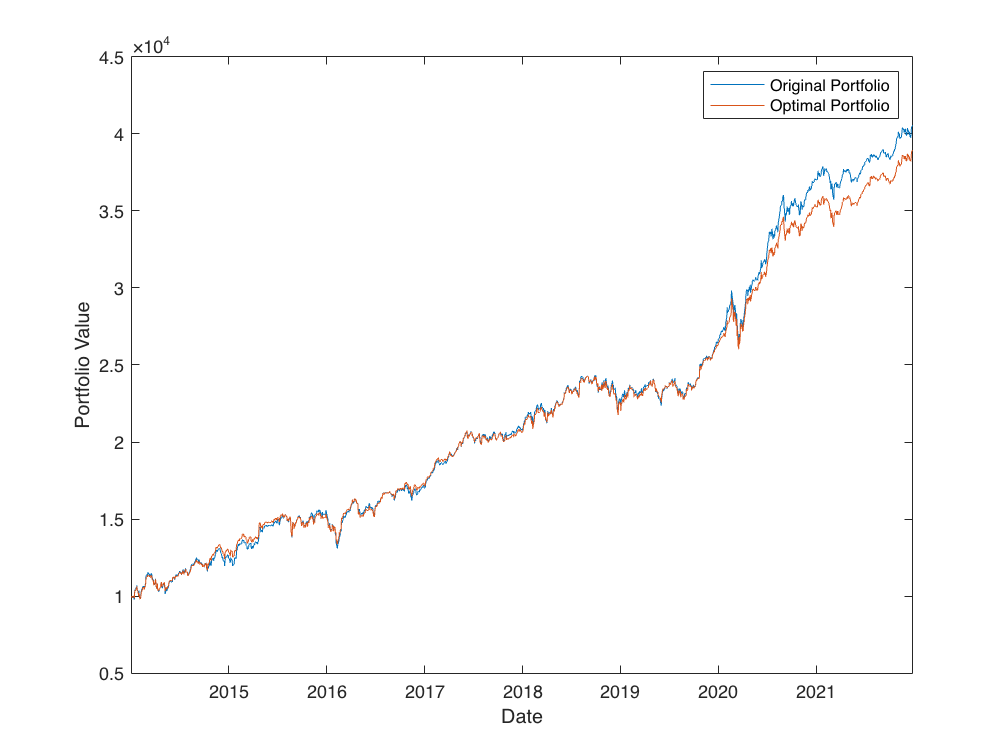

% Calculate portfolio returns 

t = tiledlayout(1, 1, 'TileSpacing', 'compact');

portfolio_returns_original = dailyReturn * original_weights;
portfolio_returns_optimal  = dailyReturn * optimal_weights;

ratio = sharpe1/sharpe2;

% Integrate to calculate price of each portfolio
portfolio_value_original = 1e4 * cumsum([1; portfolio_returns_original]);
portfolio_value_optimal  = 1e4 * cumsum([1; portfolio_returns_optimal]);


dates = history.Date;

portfolio_returns_tt = timetable(dates(2:end), portfolio_returns_original, portfolio_returns_optimal);


% Plot price for both portfolios simultaneously
plot(dates, portfolio_value_original,'DisplayName','Original Portfolio')
hold on
plot(dates, portfolio_value_optimal,'DisplayName','Optimal Portfolio')
xlabel("Date");
ylabel("Portfolio Value");
legend({'Original Portfolio' 'Optimal Portfolio'});
hold off

### Portfolio Chart Data

% Calculations
annualized_portfolio_returns = retime(portfolio_returns_tt, "yearly","sum");


% Outputs 
start_balance = [portfolio_value_original(1) portfolio_value_optimal(1)];
end_balance = [portfolio_value_original(end) portfolio_value_optimal(end)];
annualized_return = [mean(annualized_portfolio_returns.portfolio_returns_original) mean(annualized_portfolio_returns.portfolio_returns_optimal)];
standard_deviation = [std(annualized_portfolio_returns.portfolio_returns_original) std(annualized_portfolio_returns.portfolio_returns_optimal)];
best_year = [max(annualized_portfolio_returns.portfolio_returns_original) max(annualized_portfolio_returns.portfolio_returns_optimal)];
worst_year = [min(annualized_portfolio_returns.portfolio_returns_original) min(annualized_portfolio_returns.portfolio_returns_optimal)];
max_drawdown = [maxdrawdown(portfolio_value_original) maxdrawdown(portfolio_value_optimal)];
sharpe_ratio = annualized_return ./ standard_deviation;

data = [start_balance; end_balance; annualized_return; standard_deviation; 
    best_year; worst_year; max_drawdown; sharpe_ratio];

results = array2table(data, 'VariableNames', {'Provided Portfolio', 'Optimal Portfolio'});

ans = 8×2 table
    Provided Portfolio    Optimal Portfolio
    __________________    _________________

           10000                 10000     
           40553                 38952     
         0.38192                0.3619     
         0.28498               0.22958     
          1.0604               0.90323     
          0.1558               0.19696     
         0.16077               0.13111     
          1.3402                1.5764     
